%% Instrument Classification Demo (robust, with consistent preprocessing)
%% Auto setup project path
% Automatically add all subfolders under project root to MATLAB path

%% === Robust project path & model loading (portable) ===
clear; clc;

% 1) Resolve where we are (Live Editor safe)
try
    thisFile = matlab.desktop.editor.getActiveFilename;
catch
    thisFile = '';
end
if ~isempty(thisFile)
    here = fileparts(thisFile);
else
    here = pwd;
end

% 2) Walk up to find a folder that has both 'src' and 'results'
root = here;
for k = 1:8
    if isfolder(fullfile(root,'src')) && isfolder(fullfile(root,'results'))
        break
    end
    parent = fileparts(root);
    if strcmp(parent, root)  % reached filesystem root
        error("Cannot locate project root containing both 'src' and 'results' folders.\nStart from inside your project.");
    end
    root = parent;
end
projectRoot = root;

% 3) Add source code to path
addpath(genpath(fullfile(projectRoot,'src')));

% 4) Model file (train script writes here)
modelFile = fullfile(projectRoot,'results','ml','instrument_classifier.mat');

% 5) Load model (with helpful error if missing)
if ~isfile(modelFile)
    error(['Model not found at:\n  %s\n' ...
           '→ Please run train_instrument_classifier.mlx first to create it.'], ...
           modelFile);
end

% 6) Load required vars; tolerate missing open-set fields
S = load(modelFile, 'Mdl','mu','sigma','uniqueLabels','openSet','classStats');

% Unpack
Mdl          = S.Mdl;
mu           = S.mu;
sigma        = S.sigma;
uniqueLabels = S.uniqueLabels;

% Open-set thresholds (defaults if absent)
if isfield(S,'openSet') && ~isempty(S.openSet)
    openSet = S.openSet;
else
    openSet = struct('prob_threshold',0.45,'min_vote_share',0.40);
    warning('[OpenSet] Using default thresholds: prob=0.45, vote=0.40.');
end

% Mahalanobis stats (optional)
useMahalanobis = isfield(S,'classStats') && ~isempty(S.classStats);
if useMahalanobis
    classStats = S.classStats;
else
    warning('[OpenSet] classStats missing; Mahalanobis check will be skipped.');
end

fprintf('[PATH] Project root : %s\n', projectRoot);

[PATH] Project root : D:\2025S2\ELEC5305\Project\elec5305-project-510019277\elec5305-project-510019277


fprintf('[PATH] Model file   : %s\n\n', modelFile);

[PATH] Model file   : D:\2025S2\ELEC5305\Project\elec5305-project-510019277\elec5305-project-510019277\results\ml\instrument_classifier.mat



% -------- 1) Read the audio and resample it to 16 kHz --------
testFile = "demo_data/Unknown_Instrument/saxophone_G3_phrase_mezzo-forte_staccato.mp3"; % Change to any test audio
[x, fs] = audioread(testFile);
if size(x,2)>1, x = mean(x,2); end
if fs ~= 16000, x = resample(x, 16000, fs); end
fs = 16000;

% -------- 2) Preprocessing consistent with training: noise removal + amplitude normalization --------
x = trim_silence_local(x, 2048, 0.02);   
x = x ./ max(1e-9, abs(x));        

% -------- 3) Segmentation-based prediction for long audio (more stable) --------
winDur = 0.8;              
hopDur = 0.4;              
wlen   = round(winDur*fs);
hop    = round(hopDur*fs);

N = numel(x);
starts = 1:hop:max(1, N-wlen+1);

Feats = [];
for s = starts
    seg = x(s:min(N, s+wlen-1));


    seg = trim_silence_local(seg, 1024, 0.02);
    if numel(seg) < round(0.3*fs)   
        continue;
    end
    seg = seg ./ max(1e-9, abs(seg));


    f = extract_features_local(seg, fs);
    Feats = [Feats; f]; %#ok<AGROW>
end

if isempty(Feats)
    error("There are too few valid speech segments, making it impossible to extract features. Please select a clearer audio segment and try again.");
end


Feats = (Feats - mu) ./ (sigma + 1e-6);

% -------- 4) Segmented prediction + Voting / Confidence statistics --------
if isa(Mdl,'TreeBagger')
    [yp_batch, score] = predict(Mdl, Feats);           % yp_batch is cellstr
    yp_batch = categorical(yp_batch, cellstr(uniqueLabels));
else
    [yp_batch, score] = predict(Mdl, Feats);           % fitcecoc: categorical + score
end

% Multiple voting: Take the mode as the final category
[finalLabel, ~, grp] = mode(yp_batch);
% At the same time, calculate the average confidence level (the average of all scores is taken)
meanScore = mean(score, 1);
[~, idxTop] = sort(meanScore, 'descend');

fprintf('\n=== Segment-wise Voting Result ===\n');


=== Segment-wise Voting Result ===


fprintf('Segments used: %d\n', numel(grp));

Segments used: 1


fprintf('Predicted Instrument (majority vote): %s\n', string(finalLabel));

Predicted Instrument (majority vote): viola


fprintf('Top-3 by mean score:\n');

Top-3 by mean score:


for k = 1:min(3, numel(idxTop))
    fprintf('  %d) %s  (%.3f)\n', k, string(uniqueLabels(idxTop(k))), meanScore(idxTop(k)));
end

  1) viola  (-0.123)
  2) trombone  (-0.220)
  3) flute  (-0.315)


%% -------- 4.x) First, calculate the common statistics：probTop / voteShare / Mahalanobis -------

% (a) Average confidence level of the category (in the RF case, this is the average of the posterior probabilities)
prob_per_class = mean(score, 1);               % 1 x C
[probTop, kTop_prob] = max(prob_per_class);

% (b) Consistency rate of segmented voting
modeLab    = mode(yp_batch);                   
vote_share = mean(yp_batch == modeLab);        

% (c) mahalanobis distance
dmin = NaN; tau_near = NaN; idxNear = NaN;
if useMahalanobis
    featMean_all = mean(Feats, 1);             % 1 x p
    Ccls = numel(classStats.classes);
    d_maha = zeros(1, Ccls);
    for c = 1:Ccls
        mu_c   = classStats.mu(c,:);           % 1 x p
        iSig_c = classStats.invSigma(:,:,c);   % p x p
        diff_c = featMean_all - mu_c;          % 1 x p
        d_maha(c) = sqrt( max(0, diff_c * iSig_c * diff_c.') );
    end
    [dmin, idxNear] = min(d_maha);
    tau_near = classStats.tau_maha(idxNear);
end

%% -------- 4.y)Comparison 1: Decisions made without a voting mechanism (baseline)  --------
% Here, we simulate the situation where "only probTop + Mahalanobis rules are applied, without the voteShare rule".

rule_prob_noVote = (probTop < openSet.prob_threshold);
rule_maha_noVote = useMahalanobis && (dmin > tau_near);

isUnknown_noVote = rule_prob_noVote || rule_maha_noVote;

if isUnknown_noVote
    label_noVote = categorical("Unknown Instrument");
else
    % Regardless of the segmented voting, always select the category with the highest overall average confidence level.
    label_noVote = categorical(string(uniqueLabels(kTop_prob)));
end

fprintf('\n>>> Baseline decision WITHOUT voting:\n');


>>> Baseline decision WITHOUT voting:


fprintf('    Predicted label (no vote) : %s\n', string(label_noVote));

    Predicted label (no vote) : viola


fprintf('    probTop = %.3f (th = %.2f), ', probTop, openSet.prob_threshold);

    probTop = -0.123 (th = -0.12), 

if useMahalanobis
    fprintf('dmin = %.3f, tau = %.3f (Mahalanobis used)\n', dmin, tau_near);
else
    fprintf('(Mahalanobis disabled)\n');
end

dmin = 3.372, tau = 8.377 (Mahalanobis used)



%% -------- 4.z)Open set discrimination with voteShare -------

rule_prob  = (probTop   < openSet.prob_threshold);
rule_vote  = (vote_share < openSet.min_vote_share);
rule_maha  = useMahalanobis && (dmin > tau_near);

isUnknown = rule_prob || rule_vote || rule_maha;

if isUnknown
    finalLabel = categorical("Unknown Instrument");
    fprintf('\n*** Open-set rule (WITH voting) -> Unknown Instrument ***\n');
    if useMahalanobis
        fprintf('Reasons: probTop=%.3f(th=%.2f) | voteShare=%.2f(th=%.2f) | dmin=%.3f(tau=%.3f)\n', ...
            probTop, openSet.prob_threshold, vote_share, openSet.min_vote_share, dmin, tau_near);
    else
        fprintf('Reasons: probTop=%.3f(th=%.2f) | voteShare=%.2f(th=%.2f) | (Mahalanobis disabled)\n', ...
            probTop, openSet.prob_threshold, vote_share, openSet.min_vote_share);
    end
else

    fprintf('\n*** Open-set rule (WITH voting) keeps label: %s ***\n', string(finalLabel));
    fprintf('Details: probTop=%.3f(th=%.2f) | voteShare=%.2f(th=%.2f)\n', ...
        probTop, openSet.prob_threshold, vote_share, openSet.min_vote_share);
end


*** Open-set rule (WITH voting) -> Unknown Instrument ***


Reasons: probTop=-0.123(th=-0.12) | voteShare=0.56(th=0.70) | dmin=3.372(tau=8.377)


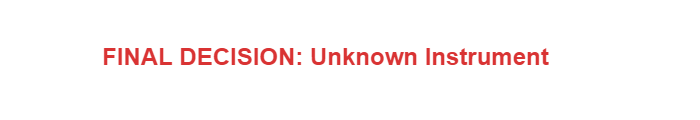


%% === Final Decision Banner） ===
if isUnknown
    finalText  = 'FINAL DECISION: Unknown Instrument';
    finalColor = [0.85 0.2 0.2];   
else
    finalText  = ['FINAL DECISION: ' char(finalLabel)];
    finalColor = [0.2 0.6 0.2];    
end

figure('Name','Decision Banner','Position',[100 100 700 120]); 
axis off;
text(0.02,0.5, finalText, 'FontSize',18, 'FontWeight','bold', 'Color',finalColor);



fprintf('\n=== FINAL DECISION (WITH voting): %s ===\n', string(finalLabel));


=== FINAL DECISION (WITH voting): Unknown Instrument ===


if useMahalanobis && ~isnan(idxNear)
    nearName = string(classStats.classes(idxNear));
else
    nearName = "(n/a)";
end
fprintf('Details: probTop=%.3f (th=%.2f), voteShare=%.2f (th=%.2f), nearest=%s, dmin=%.3f, tau=%.3f\n', ...
    probTop, openSet.prob_threshold, vote_share, openSet.min_vote_share, nearName, dmin, tau_near);

Details: probTop=-0.123 (th=-0.12), voteShare=0.56 (th=0.70), nearest=viola, dmin=3.372, tau=8.377


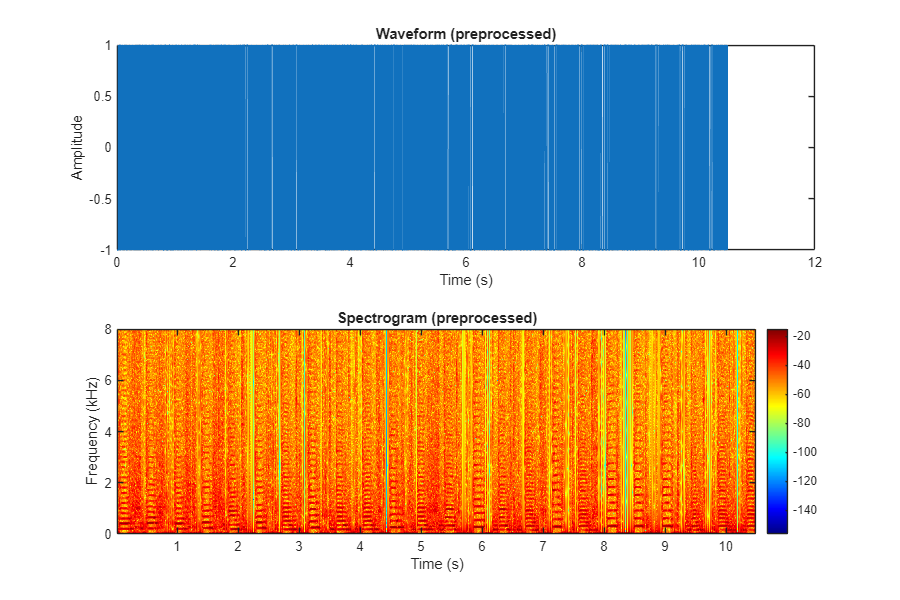

% -------- 5) visualization --------
figure('Name','Demo Visualization','Position',[100 100 900 600]);
subplot(2,1,1);
plot((0:numel(x)-1)/fs, x);
xlabel('Time (s)'); ylabel('Amplitude');
title("Waveform (preprocessed)");

subplot(2,1,2);
spectrogram(x, hann(512), 256, 1024, fs, 'yaxis');
title("Spectrogram (preprocessed)");
colormap jet;
colorbar;


%% ========== Local auxiliary function: Consistent with training ==========
function y = trim_silence_local(x, wlen, thr)
    x = x(:);
    w = hann(wlen,'periodic'); 
    hop = round(wlen/2);
    M = max(1,floor((numel(x)-wlen)/hop)+1);
    e = zeros(M,1);
    for i=1:M
        seg = x((i-1)*hop+1 : min(numel(x),(i-1)*hop+wlen));
        seg = seg .* w(1:numel(seg));
        e(i) = sum(seg.^2);
    end
    e = e ./ max(e+1e-12);
    i1 = find(e>thr,1,'first'); if isempty(i1), i1=1; end
    i2 = find(e>thr,1,'last');  if isempty(i2), i2=M; end
    s = max(1,(i1-1)*hop+1);
    t = min(numel(x),(i2-1)*hop+wlen);
    y = x(s:t);
end


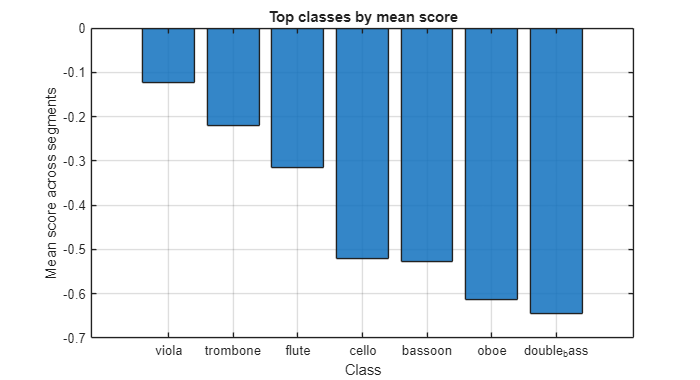

%% ========= Visualize each level of confidence =========
classNames = cellstr(uniqueLabels);  
segTimes   = (starts-1)/fs;           
numSeg     = size(score,1);
[~, topIdxSeg] = max(score, [], 2);  

% 1) Global Top-K Average Score Bar Chart
meanScore = mean(score, 1);                 % 1 x C
[meanScoreSorted, idxTop] = sort(meanScore, 'descend');
K = min(7, numel(idxTop));                  
figure('Name','Mean class scores','Position',[100 100 700 380]);
bar(meanScoreSorted(1:K), 'FaceAlpha',0.85); grid on;
xticklabels(classNames(idxTop(1:K)));
ylabel('Mean score across segments'); xlabel('Class');
title('Top classes by mean score');

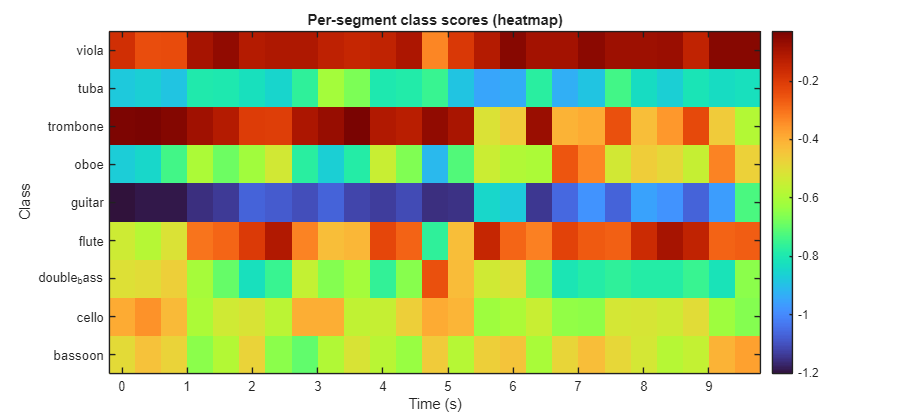


% 2) Segment × Category Heat Map (Confidence Level Changes with Time/Segment)
figure('Name','Segment-class score heatmap','Position',[100 100 900 420]);
imagesc(segTimes, 1:numel(classNames), score');  
axis xy; colormap turbo; colorbar;
yticks(1:numel(classNames)); yticklabels(classNames);
xlabel('Time (s)'); ylabel('Class');
title('Per-segment class scores (heatmap)');

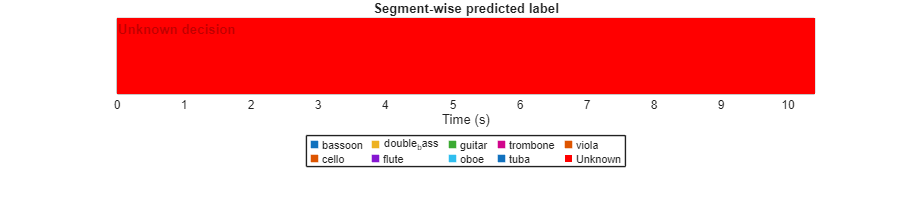


% 3) Segment-level predictions on the timeline (each category in different colors + Unknown overlay)
figure('Name','Segment predictions over time','Position',[100 100 900 200]);
ax4 = gca; hold(ax4,'on');

% Color according to the "each prediction label yp_batch"
classNames = cellstr(uniqueLabels);      
labStr     = cellstr(string(yp_batch));  
[~, clsIdx] = ismember(labStr, classNames); 
cmap = lines(numel(classNames));         

segTimes = (starts-1)/fs;               
numSeg   = size(score,1);
isRF     = isa(Mdl,'TreeBagger');       

segProbThr = 0.30;        
unkCol     = [1 0 0];   

for i = 1:numSeg
    t0 = segTimes(i); 
    t1 = t0 + (wlen/fs);

    if isUnknown

        faceCol = unkCol;

    else

        if isRF

            conf_i = max(score(i,:));       
            if conf_i < segProbThr
                faceCol = [0.5 0.5 0.5]; 
            else
                k = clsIdx(i); if k==0, k=1; end
                faceCol = cmap(k,:);
            end
        else

            k = clsIdx(i); if k==0, k=1; end
            faceCol = cmap(k,:);
        end
    end

    rectangle('Position', [t0 0 t1-t0 1], ...
              'FaceColor', faceCol, 'EdgeColor', 'none', 'Parent', ax4);
end


if isUnknown
    yl = ylim(ax4);
    hShade = patch(ax4, ...
        [segTimes(1) segTimes(end)+wlen/fs segTimes(end)+wlen/fs segTimes(1)], ...
        [yl(1)       yl(1)                 yl(2)                 yl(2)], ...
        [1 0 0], 'FaceAlpha', 0.10, 'EdgeColor', 'none');
    uistack(hShade,'top');

    text(ax4, segTimes(1)+0.02, yl(2)-0.05*(yl(2)-yl(1)), ...
        'Unknown decision', 'Color', [0.75 0 0], ...
        'FontWeight', 'bold', 'VerticalAlignment','top');
end

xlim(ax4, [segTimes(1), segTimes(min(numSeg,end)) + wlen/fs]);
ylim(ax4, [0 1]); yticks(ax4, []); box(ax4, 'on');
xlabel(ax4, 'Time (s)'); 
title(ax4, 'Segment-wise predicted label');


K = numel(classNames);
ph = gobjects(K,1);
for k = 1:K
    ph(k) = plot(ax4, nan, nan, 's', ...
        'MarkerFaceColor', cmap(k,:), ...
        'MarkerEdgeColor', cmap(k,:), ...
        'MarkerSize', 8, ...
        'DisplayName', char(classNames{k}));
end

hUnk = plot(ax4, nan, nan, 's', ...
    'MarkerFaceColor', [1 0 0], 'MarkerEdgeColor', 'none', ...
    'MarkerSize', 8, 'DisplayName', 'Unknown');

legend(ax4, [ph; hUnk], [classNames; {'Unknown'}], ...
    'Location', 'southoutside', ...
    'NumColumns', min(8, K+1));




% 4) 
outCsv = fullfile('results','ml','demo_segment_scores.csv');
if ~isfolder(fileparts(outCsv)), mkdir(fileparts(outCsv)); end


[~, idx2] = sort(meanScore, 'descend');      % 1 x C 


Tmeta = table( (1:numSeg).', ...
               segTimes(:), ...
               segTimes(:) + wlen/fs, ...
               string(yp_batch(:)), ...
               'VariableNames', {'seg','t0','t1','pred'});

% 4.2 
scoreNames = "score_" + string(classNames(idx2));      % string 
Tscore = array2table( score(:, idx2), ...
                      'VariableNames', cellstr(scoreNames) );

% 4.3 
T = [Tmeta Tscore];
writetable(T, outCsv);
fprintf('Per-segment scores saved to: %s\n', outCsv);

Per-segment scores saved to: results\ml\demo_segment_scores.csv
